# Training Unit 3: RLC Simulation

Fink Lucas / Teichtmeister Marcus, 15.10.2025

## MATLAB Setup

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Task

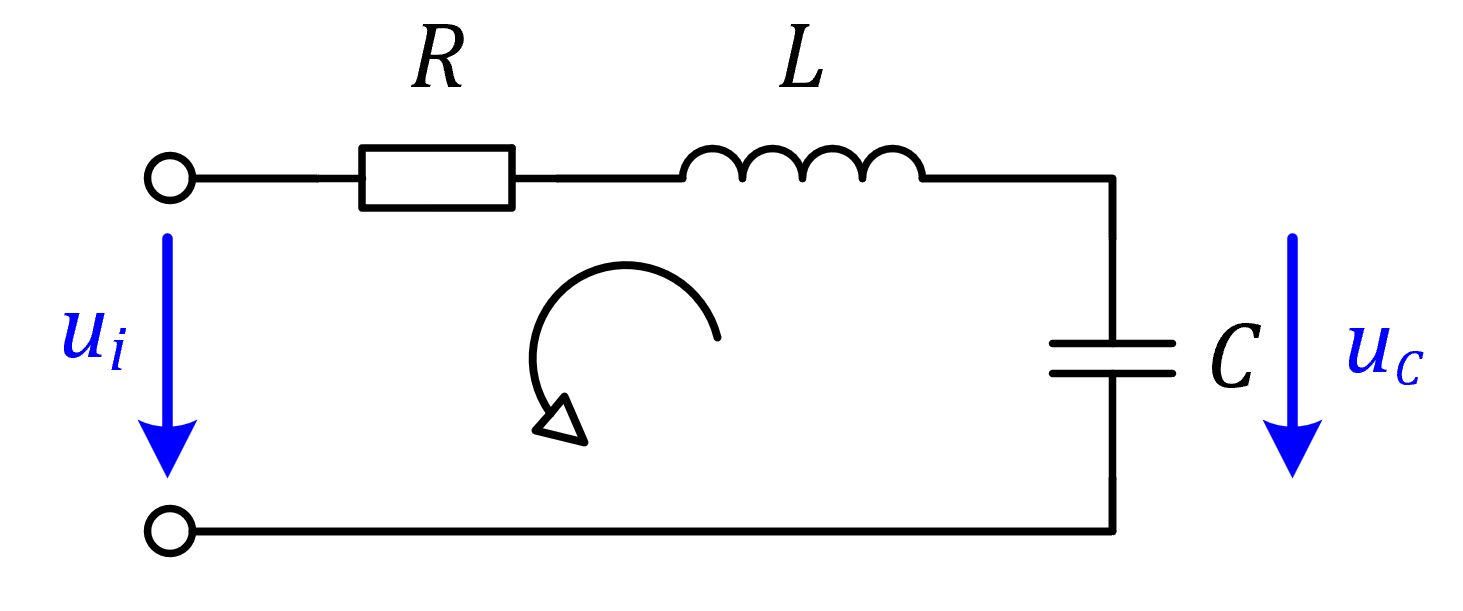

The voltage of the capacitor $u_c$ needs to be simulated using different methods:

- solving the ordinary differential equation on Simulink

- simulate the circuit on Simscape

- simulate the circuit on LTSpice

- solving it with its transfer function

## Deriving the differential equation of the RLC circuit

With the help of Kirchhoff's voltage law and the relationship between inductance / capacitance and current / voltage, it is possible to derive the needed ODE. It is also important to say, that the input voltage is a heaviside function, which has its step at 2 seconds and an amplitude of 3V.


$$\sum u=0\mathrm{V}:u_i -u_R -u_L -u_C =0\mathrm{V}$$


$i=C\;\frac{\textrm{d}}{\textrm{d}\mathrm{t}}u$ and $u=L\;\frac{\textrm{d}}{\textrm{d}\mathrm{t}}i$

The voltage of the capacitor is needed, therefore only the input voltage and the capacitor voltage have to be in the ODE. According to the schematic all elements are in series, hence only one current exists and can be described with the capacitance.

                    
$$i=C\frac{\;\mathrm{d}\;u_C }{\mathrm{d}\;\mathrm{t}\;}$$


Voltage of resistor and inductor can also be described with the current:

                    $u_R =i\cdot R=R\;C\frac{{\mathrm{d}\;u}_C \;}{\mathrm{dt}}$ and $u_L =L\frac{\;\mathrm{d}\;i}{\mathrm{dt}}=L\;\frac{\mathrm{d}}{\mathrm{dt}}C\;\frac{\mathrm{d}\;u_C }{\mathrm{dt}}=L\;C\;\frac{{\mathrm{d}}^2 \;u_C }{{\mathrm{dt}}^2 }$

                    
$$u_i -u_C -R\;C\frac{\;{\mathrm{d}\;u}_C }{\mathrm{dt}}-L\;C\frac{\;{\mathrm{d}}^2 \;u_C }{\;\mathrm{dt}}=0\mathrm{V}$$


Now it is possible to either derive the explicite expression of the ODE or its transfer function.

    Explicite Expression:

                    
$$\frac{{\mathrm{d}}^{2\;} u_C }{{\mathrm{dt}}^2 }=\frac{1}{L\;C}\;u_i -\frac{1}{L\;C}\;u_C -\frac{R}{L}\frac{\;\mathrm{d}\;u_C }{\mathrm{dt}}=\frac{1}{L\;C}\;\left(u_i -u_C -R\;C\frac{\;\mathrm{d}\;u_C }{\mathrm{dt}}\right)$$


    Transfer Function:

                    
$$\mathcal{L}\;\left\lbrace u_i \right\rbrace =\mathcal{L}\;\left\lbrace u_C +R\;C\frac{\;{\mathrm{d}\;u}_C }{\mathrm{dt}}+L\;C\frac{\;{\mathrm{d}}^2 \;u_C }{\;\mathrm{dt}}\right\rbrace$$


                    
$$\breve{\;u_i } \frac{\;e^{-2s} }{s}=\breve{\;u_C } +s\;R\;C\;\breve{\;u_C } +s^2 \;L\;C\;\breve{\;u_C } =\breve{\;u_C } \left(1+sRC+s^2 LC\right)$$


                    
$$G\left(s\right)=\frac{\breve{\;u_C } }{\breve{\;u_i } }=\frac{e^{-2s} }{s+s^2 RC+s^3 LC}$$


                    For Simulink it is sufficient to type the delay into the step block and the term $\frac{e^{-2s} }{s}$ is not needed in the transfer function block. 

### Simulation

Die Grafik soll bereits vor $t=0$ beginnen, und bis zu einer definierten Endzeit 

Endzeit für Grafik

Sim.t_plot_end = 10;

Verzögerung für Sprung

Sim.t_step = 2;

Endzeit der Simulation 

Sim.t_end = Sim.t_plot_end + Sim.t_step;

Parameter

RLC.u_i = 3;
RLC.R = 56000;
RLC.L = 100e-6;
RLC.C = 10e-6;

Importing LTspice Data

filename ='./LTSpice/RLC_Serial.txt';

ltspice_data = readtable(filename, 'Delimiter', '\t', 'ReadVariableNames', true);

ltspice_data.Properties.VariableNames = {'Time in s', 'u_c in V', 'u_i in V'};
ltspice_data

ltspice_data = 30×3 table
    Time in s     u_c in V     u_i in V
    _________    __________    ________

          0               0          0 
          2               0          0 
          2      5.3561e-06        0.3 
          2      2.6782e-05        0.9 
     2.0001      7.6475e-05     1.5747 
     2.0001      0.00015092     2.2319 
     2.0001      0.00027051          3 
     2.0001      0.00028518          3 
     2.0129        0.068117          3 
     2.0257         0.13449          3 
     2.0386         0.19941          3 
     2.0514         0.26288          3 
     2.0642         0.32489          3 
      2.077         0.38545          3 
     2.0898         0.44455          3 
     2.1796         0.82368          3 


open('RLC_Simulation.slx')

sim('RLC_Simulation.slx')

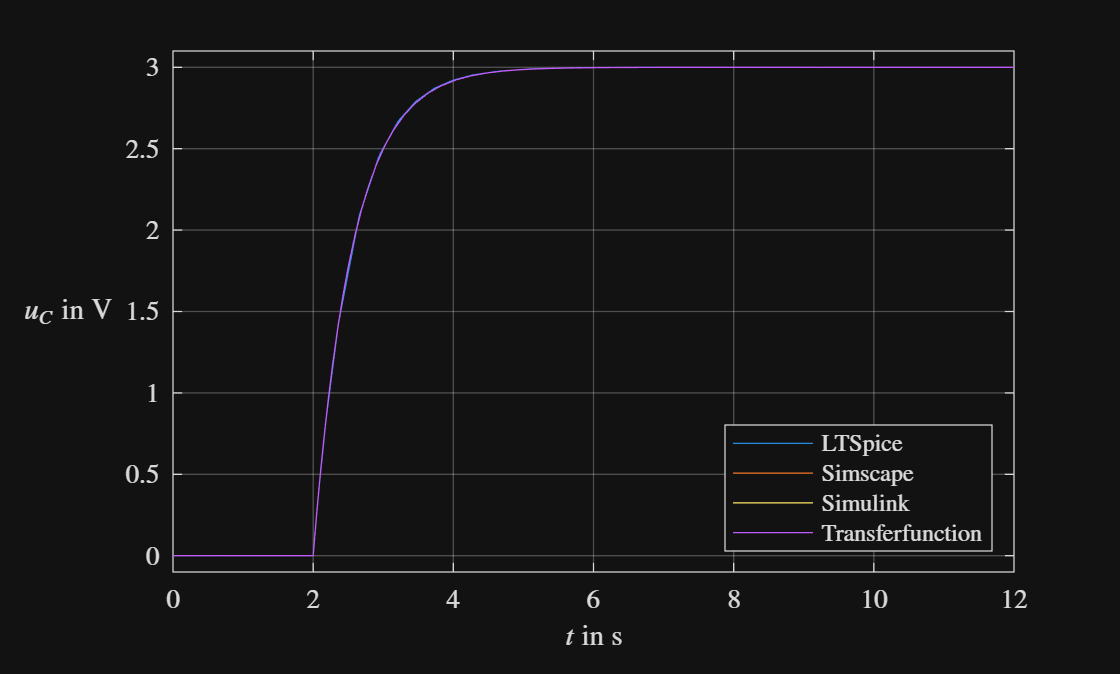

figure

tiledlayout(1, 1)

pl1 = nexttile;
plot(ltspice_data.("Time in s"), ltspice_data.("u_c in V"),'DisplayName','LTSpice')
hold on
plot(RLC_SIM.get('uc_simscape').Values.Time, RLC_SIM.get("uc_simscape").Values.Data, 'DisplayName','Simscape')
plot(RLC_SIM.get('uc_simulink').Values.Time, RLC_SIM.get("uc_simulink").Values.Data, 'DisplayName','Simulink')
plot(RLC_SIM.get('uc_transferfunction').Values.Time, RLC_SIM.get("uc_transferfunction").Values.Data,'DisplayName','Transferfunction')
grid('on')
axis([0, Sim.t_end, -0.1, 3.1])
ylabel('$u_C$ in V')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

xlabel('$t$ in s')
legend('Location', 'southeast')

The figure shows, that all methods lead to the same result.